# Machine Learning Online Class

## Initialization

clear ; close all; clc

## =============== Part 1: Loading and Visualizing Data ================

fprintf('Loading and Visualizing Data ...\n')

Loading and Visualizing Data ...



% Load from ex6data1: 
% You will have X, y in your environment
load('ex6data1.mat');

% Plot training data
plotData(X, y);

fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


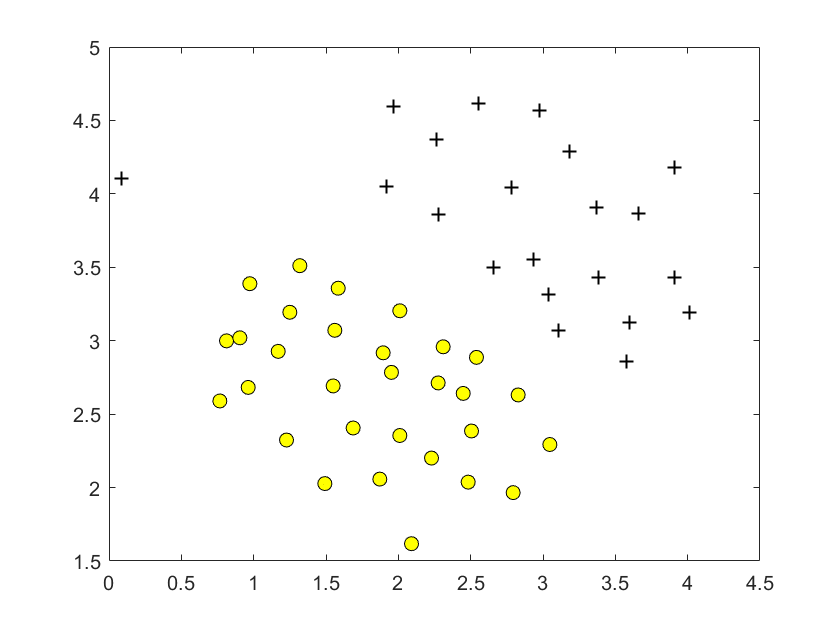

pause;

## ==================== Part 2: Training Linear SVM ====================

% Load from ex6data1: 
% You will have X, y in your environment
load('ex6data1.mat');

fprintf('\nTraining Linear SVM ...\n')

% You should try to change the C value below and see how the decision
% boundary varies (e.g., try C = 1000)
C = 1;
model = svmTrain(X, y, C, @linearKernel, 1e-3, 20);
visualizeBoundaryLinear(X, y, model);

fprintf('Program paused. Press enter to continue.\n');
pause;

## =============== Part 3: Implementing Gaussian Kernel ===============

fprintf('\nEvaluating the Gaussian Kernel ...\n')

x1 = [1 2 1]; x2 = [0 4 -1]; sigma = 2;
sim = gaussianKernel(x1, x2, sigma);

fprintf(['Gaussian Kernel between x1 = [1; 2; 1], x2 = [0; 4; -1], sigma = %f :' ...
         '\n\t%f\n(for sigma = 2, this value should be about 0.324652)\n'], sigma, sim);

fprintf('Program paused. Press enter to continue.\n');
pause;

## =============== Part 4: Visualizing Dataset 2 ================

fprintf('Loading and Visualizing Data ...\n')

% Load from ex6data2: 
% You will have X, y in your environment
load('ex6data2.mat');

% Plot training data
plotData(X, y);

fprintf('Program paused. Press enter to continue.\n');
pause;

## ========== Part 5: Training SVM with RBF Kernel (Dataset 2) ==========

fprintf('\nTraining SVM with RBF Kernel (this may take 1 to 2 minutes) ...\n');

% Load from ex6data2: 
% You will have X, y in your environment
load('ex6data2.mat');

% SVM Parameters
C = 1; sigma = 0.1;

% We set the tolerance and max_passes lower here so that the code will run
% faster. However, in practice, you will want to run the training to
% convergence.
model= svmTrain(X, y, C, @(x1, x2) gaussianKernel(x1, x2, sigma)); 
visualizeBoundary(X, y, model);

fprintf('Program paused. Press enter to continue.\n');
pause;

## =============== Part 6: Visualizing Dataset 3 ================

fprintf('Loading and Visualizing Data ...\n')

% Load from ex6data3: 
% You will have X, y in your environment
load('ex6data3.mat');

% Plot training data
plotData(X, y);

fprintf('Program paused. Press enter to continue.\n');
pause;

## ========== Part 7: Training SVM with RBF Kernel (Dataset 3) ==========

%  This is a different dataset that you can use to experiment with. Try
%  different values of C and sigma here.
% 

% Load from ex6data3: 
% You will have X, y in your environment
load('ex6data3.mat');

% Try different SVM Parameters here
[C, sigma] = dataset3Params(X, y, Xval, yval);

% Train the SVM
model= svmTrain(X, y, C, @(x1, x2) gaussianKernel(x1, x2, sigma));
visualizeBoundary(X, y, model);

fprintf('Program paused. Press enter to continue.\n');
pause;